names = {'Ali', 'Fatemeh', 'Mohammad', 'Sara', 'Reza'};
for i=1:length(names)
    name = names(i);
    if strlength(name)>=5
        disp(name);
    end
end

    {'Fatemeh'}

    {'Mohammad'}



r = randi([1 100], 1);
i = 1;
while r~=i
    i = i + 1;
end
disp(r)

    81



disp(i)

    81



A = [3, 6, 8, 5, 10, 13, 2];
sum=0;
l=0;
for i=1:length(A)
    if mod(A(i),2)==0
        sum = sum + A(i);
        l = l + 1;
    end
end
disp(sum/l);

    6.5000



function b = is_prime(n)
    if n == 1
        b = false;
        return;
    end
    for i = 2:floor(n/2)
        if mod(n, i) == 0
            b = false;
            return;
        end
    end
    b = true;
end

for num = 1:100
    if is_prime(num)
        disp(num)
    end
end

     2

     3

     5

     7

    11

    13

    17

    19

    23

    29

    31

    37

    41

    43

    47

    53

    59

    61

    67

    71

    73

    79

    83

    89

    97



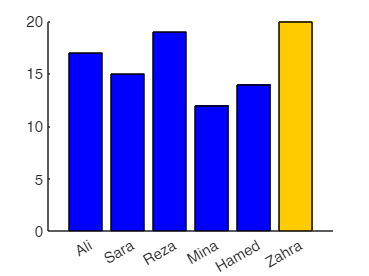

scores = [17, 15, 19, 12, 14, 20];
names = {'Ali','Sara','Reza','Mina','Hamed','Zahra'};

hold on
for i = 1:length(scores)
    if scores(i) == 20
        bar(names(i), scores(i), 'FaceColor', [1 0.8 0]); % gold
    else
        bar(names(i), scores(i), 'FaceColor', [0 0 1]); % default color
    end
end
hold off

x = -5:.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


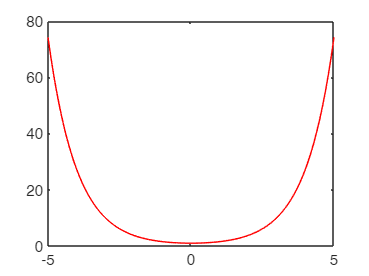

plot(x, cosh(x), 'Color', 'red')

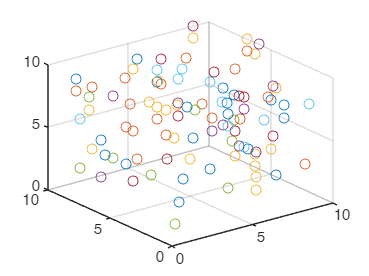

s = randi(10,[10,10,3]);
scatter3(s(:,:,1),s(:,:,2),s(:,:,3), 'Color', s(:,:,1))

sum = 0;
count = 0;
num = 1;
while sum < 1000
    sum = sum + num;
    count = count + 1;
    num = num + 2;
end

disp(count)

    32



f = [0,1]

f =      0     1


for i=3:15
    f = [f, f(i-1)+f(i-2)];
end
f

f =      0     1     1     2     3     5     8    13    21    34    55    89   144   233   377


function sorted = mergeSort(A)
    if length(A) <= 1
        sorted = A;
        return;
    end

    mid = floor(length(A) / 2);
    left = A(1:mid);
    right = A(mid+1:end);

    sortedLeft = mergeSort(left);
    sortedRight = mergeSort(right);

    sorted = merge(sortedLeft, sortedRight);
end

function result = merge(left, right)
    result = [];
    i = 1;
    j = 1;

    while i <= length(left) && j <= length(right)
        if left(i) <= right(j)
            result(end+1) = left(i);
            i = i + 1;
        else
            result(end+1) = right(j);
            j = j + 1;
        end
    end

    result = [result, left(i:end), right(j:end)];
end
A = [38, 27, 43, 3, 9, 82, 10];
mergeSort(A)

ans =      3     9    10    27    38    43    82


x = 2;
tolerance = 1e-6;

f = @(x) x^3 - 2*x^2 + 4*x - 8;
df = @(x) 3*x^2 - 4*x + 4;

while abs(f(x)) > tolerance
    x = x - f(x) / df(x);
end

disp(x)

     2



disp(f(x))

     0



f = @(x) log(x);
x = 2;
h = .01;
fp= (f(x + h) - f(x - h)) / (2 * h);
relative_error = abs(fp - .5) / .5;
disp(fp)

    0.5000



disp(relative_error)

   8.3335e-06



% syntax error:
% disp(2;
% solution:
disp(2);

     2




% runtime error:
% v = [1,2,3];
% v(4);
% solution:
v = [1,2,3];
v(3);

% logical error:
% if 2+2==5
%   disp('2+2=4');
% end
% solution:
if 2+2==4
  disp('2+2=4');
end

2+2=4


% n = input('Enter a positive integer: ');
n=7

n = 7

sum = 0;
for i = 2:n
    isPrime = true;
    for j = 2:i-1
        if mod(i, j) == 0
            isPrime = false;
            break;
        end
    end
    if isPrime == true
        sum = sum + i;
    end
end
disp(['The sum of prime numbers less than ', num2str(n), ' is: ', num2str(sum)])

The sum of prime numbers less than 7 is: 17


names = {'Ali', 'Sara', 'Reza', 'Mina', 'Hamed'};
grades = [17, 19, 14, 18, 20];

total = 0;
maxGrade = 0;

for i = 1:length(names)
    total = total + grades(i);
    if grades(i) > maxGrade
        maxGrade = grades(i);
        topStudent = names{i};
    end
end

avg = total / length(grades);
disp(['Average grade is: ', num2str(avg)]);

Average grade is: 17.6


disp(['Top student is: ', topStudent, ' with grade ', num2str(maxGrade)]);

Top student is: Hamed with grade 20


f = @(x) x^3 - 2*x^2 + 4*x - 8;
df = @(x) 3*x^2 - 4*x + 4;
x0 = 2;  
tolerance = 1e-6;
maxIter = 50;
x = x0;

for i = 1:maxIter
    x = x - f(x) / df(x);
    if abs(f(x)) < tolerance
        break;
    end
end

disp('Root found: ');

Root found: 


disp(x);

     2

